# Obstacle avoidance based on LIDAR

Obstacle avoidance is a fundamental capability for any mobile robot.

lidar = LidarSensor;
lidar.sensorOffset = [0,0]; % Offset in [m] from robot center
lidar.scanAngles = linspace(-pi/2,pi/2,51); % define  how many lasers and the angle of each one.
lidar.maxRange = .7; %Max distance range [m]

%Load a image as occupancy map.
generateMap(which('world1.png'), 0.1, 10);

%Create a visualizer and assign  the  binaryOccupancyMap.
robotRadius = .075;
viz = Visualizer2D;
viz.mapName = 'map';
viz.robotRadius = robotRadius;

%Attach sensors to robot
attachLidarSensor(viz,lidar); 

% Define initial pose and a differential robot
initPose = [ 1.45; 1.5; 0]; % [x ; y ; theta]    
R = 0.3; 
L = .12; 
mobileRobot = DifferentialDrive(R,L);


%Velocity definition
v = .2; % [m/s]
w = 0; % [rad/s]
bodyV = [v;0;w];    % Body velocities [vx;vy;w]  vy = 0 because the differential robot can not move in y axis.

A LIDAR sensor is useful to avoid obstacles [here](https://www.mathworks.com/help/nav/ug/vector-field-histograms.html) is an excellent explanation of  VHF( Vector Field Histogram) that use LIDAR readings to avoid obstacles. 

The implementation is the following:

% Vector Field Histogram (VFH) for obstacle avoidance
vfh = controllerVFH;
vfh.DistanceLimits = [0.1 1];
vfh.RobotRadius = robotRadius;
vfh.SafetyDistance = .15;
vfh.MinTurningRadius = .1; 

Execute simulation.

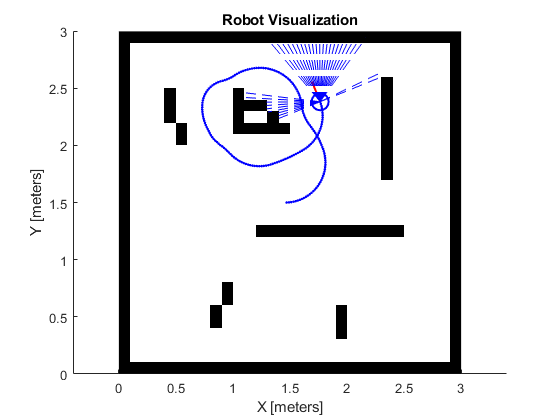

currentPose = initPose;
[sampleTime,tVec,r] = simulTime(0.1,20); % Define Sample time, time array and rate control 
for idx = 2:numel(tVec) 

    % Get the sensor readings from the real pose
    ranges = lidar(currentPose);
    targetDir = 0.5707;
    %steerDir = vfh(ranges,lidar.scanAngles,targetDir);    
    wRef = vfh(ranges,lidar.scanAngles, targetDir);
    if isnan(wRef)  
        wRef = 0.5;
    end
    
    bodyV = [v;0;wRef];
    
    % Convert from robot body to world
    vel =  bodyToWorld(bodyV,currentPose);  
   
    % Perform forward discrete integration step
    currentPose = currentPose + vel * sampleTime; 
    % Update visualization
    viz(currentPose,ranges);
    
    %Wait for visualization rate
    waitfor(r);
    
end

# Practice

### Change VFH parameters one by one and describe  how it modify the resulting obstacle avoidance. Check [this link](https://www.mathworks.com/help/nav/ref/controllervfh-system-object.html) for more information about VFH object. 